# WEC Co-optimization example

This live script presents an example co-optimization study in which the power take-off (PTO) and controller of a wave energy converter (WEC) are optimized. The process is divided into two basic steps:

- Sea state selection: the co-optimization study is dependent on the wave conditions

- WEC co-optimization: after defining the co-optimization problem, we can apply MATLAB's [`fmincon`](https://www.mathworks.com/help/optim/ug/fmincon.html) solver to obtain a solution. 

% load WEC intrinsic impedance model
mf = load('waveBot_heaveModel.mat');
Zi = mf.Zi_frf(60:end,1);
Hex = mf.H_frf(60:end,1);
f = mf.f(60:end,1);
w = 2*pi*f;
dw = w(2)-w(1);

Ri = real(Zi);  % intrinsic resistance
Xi = imag(Zi);  % intrinsic reactance

## Sea state selection

We must define a sea state on which perform the analysis. Use the controls below to define the desired sea state.

wave_type = "JS";  % select type of excitation
Tp = 2.5; % Wave Period (Peak period for Jonswap)
Hs = 1.25; % wave Height
gamma  = 3; % peakiness factor (for Jonswap)

- **Monochromatic: **A monochromatic ("regular") wave can be defined by a height and period. Note that in the interface above, these are labeled at $H_s$ and $T_p$, respectively (the $\gamma$ input is not used).

- **JONSWAP:** For a JONSWAP sea state, the spectral energy distribution can be defined by the peak period ($T_p$), the significant wave height ($H_s$), and a peakedness factor ($\gamma$). For further explanation, see [WAFO documentation](http://www.maths.lth.se/matstat/wafo/documentation/wafotutor25.pdf).

- **Unit amp. (RAO):** This option produces an input with unit amplitude across the valid frequency range of the device in question. This option can be used to produce response amplitude operator (RAO) type results.

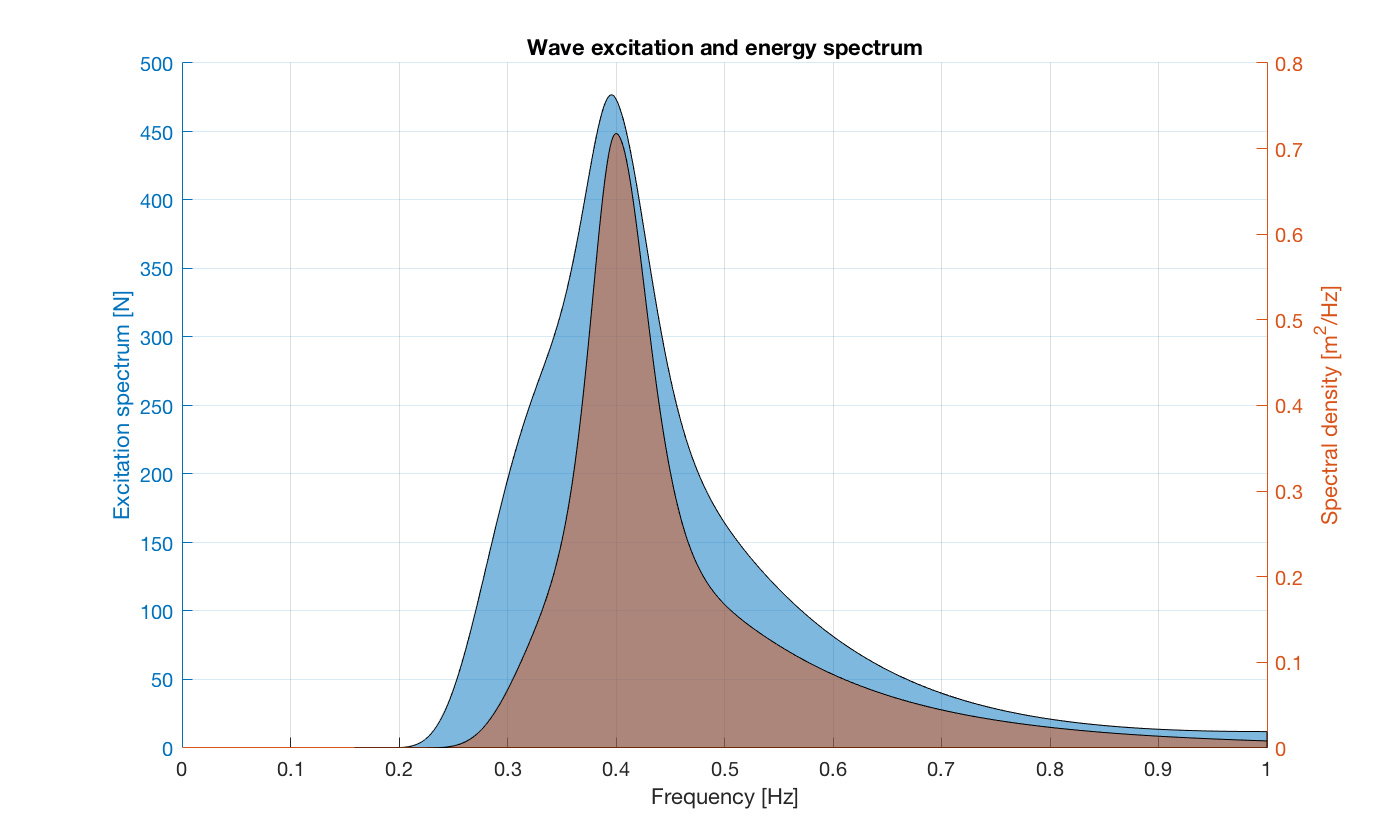


fig = figure;
fig.Position = fig.Position .* [1 1 1.25 1];
switch wave_type
    
    case 'JS'
        
        warning('off','WAFO:MKJONSWAP')
        
        S = jonswap(w, [Hs, Tp, gamma]);    % Wave energy density spectrum
        A = sqrt(2*dw*S.S(:));              % wave amplitude spectrum
        Fe = A .* Hex(:);                   % excitation spectrum
        
        hold on
        grid on
        
        yyaxis right
        ylabel('Spectral density [m^2/Hz]')
        area(f, 2*pi*S.S, 'facealpha',0.5)
        
        yyaxis left
        area(f, Fe, 'facealpha',0.5)
        
        warning('on','WAFO:MKJONSWAP')
        
    case 'Mono'
        
        f0 = floor(1/Tp*1e3)/1e3;
        [~,idx] = min(abs(f-f0));
        Fe = zeros(size(Hex));
        Fe(idx) = Hex(idx) * Hs/2; % Excitation force
        
        stem(f, Fe)
        
    case 'RAO'
        
        A = ones(length(f),1);
        Fe = A .* Hex(:);
        
        plot(f, Fe)
        
    otherwise
        error('Invalid wave type')
end

xlim([0, 1])

ylabel('Excitation spectrum [N]')
xlabel('Frequency [Hz]')
title('Wave excitation and energy spectrum')

## WEC Co-design optimization

As an example, we consider the heave mode of the experimental [WaveBot](https://mhkdr.openei.org/files/315/MASK3%20(2).pdf) device. The figure below shows a diagram of the WaveBot highlighting aspects of the PTO. The heave motion of the buoy is translated to a rotational shaft via a rack-and-pinion style transmission system to drive a permanent magnet synchronous generator (see more detail [here](https://www.sciencedirect.com/science/article/pii/S0141118717307484)).

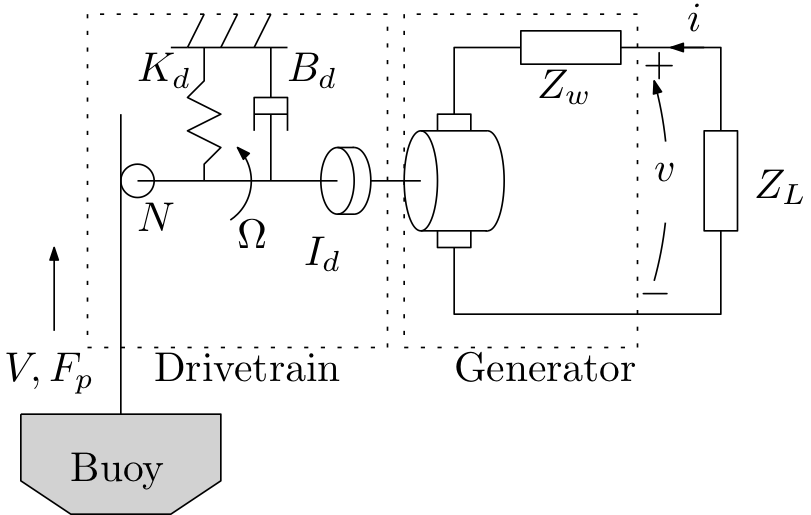

The electrical power delivered to the load is

$P_L = \frac{\frac{3}{2} \, K_t^2 N^2 \, |F_e|^2 \, R_L}{2 \left| \left( N^2 \, Z_d +Z_i \right)
	\left( Z_w +Z_L \right) + \frac{3}{2}K_t^2 N^2 \right|^2 }$.

This can be compared with the theoretical limit of the mechanical power that can be absorbed $\left( P_m^{max} = \frac{|F_{\textrm{exc}}|^2}{8 \, R_i} \right)$ to find the overall system efficiency.


$$\eta = \frac{6 \, K_t^2 N^2 \, R_i \, R_L}{2 \left| \left( N^2 \, Z_d +Z_i \right)
	\left( Z_w +Z_L \right) + \frac{3}{2}K_t^2 N^2 \right|^2 }$$


where the following variables are employed:

- Motor torque constant: $K_t$

- Gear ratio: $N$

- Intrinsic resistance: $R_i = \Re\left\{ Z_i \right\}$, where the intrinsic impedance is $Z_i = B_r + i\left( \omega\left(  M + A_r \right) -\frac{S}{\omega} \right)$ composed by the radiation damping ($B_r$), the rigid body inertia ($M$), added mass ($A_r$), and hydrostatic restoring stiffness ($S$)

- Load (controller) resistance: $R_L = \Re\left\{ Z_L \right\}$

- Drive train impedance: $Z_d = i \omega I_d  + B_d  + \frac{K_d}{i \omega}$, where $I_d$, $B_d$, and $K_d$ are the drive train inertia, damping, and spring rate, respectively

- Motor winding impedance: $Z_w= R_w + j \omega L_w$, where $R_w$ and $L_w$ are the winding resistance and inductance, respectively

We can thus perform an optimization to maximize electrical power at the load by manipulating the controller gains and the PTO parameters. 

### Problem set up

Manipulate the sliders, check boxes, and bounds below to set up a co-optimization problem. When ready press the "Run" button to execute the solver.

 

N =9; N_opt_flag = true; N_bnds = [ 1, 10 ]; % gear ratio
Kt =10; Kt_opt_flag = true; Kt_bnds = [ 3, 4 ];% Generator torque constant
Rw =0.5; Rw_opt_flag = true; Rw_bnds = [ 0.1, 4 ];% Generator winding resistance
Lw =0; Lw_opt_flag = true; Lw_bnds = [ 3, 4 ];% Generator winding inductance
Id =2; Id_opt_flag = true; Id_bnds = [ 1, 4 ];% Drivetrain total moment of inertia (including generator's rotor)
Bd =0.4; Bd_opt_flag = true; Bd_bnds = [ 3, 4 ];% Drivetrain friction
Kd =48; Kd_opt_flag = true; Kd_bnds = [ -1000000000000   , 1000000000000 ];% Drivetrain spring coefficient (between shaft and reference/ground)

PTO_param_names = {'N','Kt','Rw','Lw','Id','Bd','Kd'};
PTO_param_mask = [N_opt_flag, Id_opt_flag, Bd_opt_flag, Kd_opt_flag, Kt_opt_flag, Rw_opt_flag, Lw_opt_flag];
PTO_bounds = [N_bnds(:), Id_bnds(:), Bd_bnds(:), Kd_bnds(:), Kt_bnds(:), Rw_bnds(:), Lw_bnds(:)];
PTO_param_lb = PTO_bounds(1,PTO_param_mask);
PTO_param_ub = PTO_bounds(2,PTO_param_mask);

PTO_params = [N, Id, Bd, Kd, Kt, Rw, Lw];

% generate an initial guess and bounds
x0 = [ones(1,sum(PTO_param_mask)), zeros(1,2)];
lb = [PTO_param_lb, -1*inf(1,2)];
ub = [PTO_param_ub, inf(1,2)];

P0 = co_optimize_oneDOF_PTO_power(x0, PTO_param_mask, PTO_params, w, Zi, Fe);

coOpt_obj_fun = @(x) co_optimize_oneDOF_PTO_power(x, PTO_param_mask, PTO_params, w, Zi, Fe);
options = optimoptions('fmincon','MaxFunctionEvaluations',1e6, 'MaxIterations', 1e6,'Display','none');
[y,fval] = fmincon(coOpt_obj_fun, x0, [], [], [], [],...
    lb, ub, [], options);
P_ub = 1/8*abs(Fe).^2 ./ Ri;    % Power upper bound
P_ub_tot = sum(P_ub);


### Results

The following table and plots show the results of the co-optimization analysis. The table shows the bounds and optimal values for the design variables in the study. Below the table, the maximum theoretical power ($P_m^{max}$), the electrical power delivered to the load ($P_L$), and overall efficiency $\left( P_L / P_m^{max}  \right)$ are reported. The results are plotted in a set of two plots: the upper plot shows the maximum theoretical power ($P_m^{max}$), the electrical power delivered to the load ($P_L$); the lower plot shows the overall frequency dependent efficiency.


PTO_params(PTO_param_mask) = y(1:sum(PTO_param_mask));
[P_tot, P_o, Z_L, Z_PTO, C] = co_optimize_oneDOF_PTO_power(y, PTO_param_mask, PTO_params, w, Zi, Fe);
assert(P_tot==fval)
eta_o = P_o ./ P_ub;
overall_eff = -1*P_tot/P_ub_tot;

T = table(lb',ub',y',...
    'VariableNames',{'LowerBound','UpperBound','Optimal'},...
    'RowNames',[PTO_param_names(PTO_param_mask),'ZL_Kd','ZL_Kp']);

fprintf('Optimal parameters\n\n'), disp(T)

Optimal parameters

             LowerBound    UpperBound    Optimal
             __________    __________    _______

    N               1           10        9.9103
    Kt              1            4             1
    Rw              3            4             3
    Lw         -1e+12        1e+12       -128.48
    Id              3            4             4
    Bd            0.1            4           0.1
    Kd              3            4        3.0404
    ZL_Kd        -Inf          Inf        2652.8
    ZL_Kp        -Inf          Inf        -13199




fprintf('Max theoretical power [W]:\t%.2e',P_ub_tot)

Max theoretical power [W]:	1.25e+03

fprintf('Total power [W]:\t\t%.2e',-1*P_tot)

Total power [W]:		9.51e+02

fprintf('Overall efficiency [ ]:\t\t%.2f',overall_eff)

Overall efficiency [ ]:		0.76

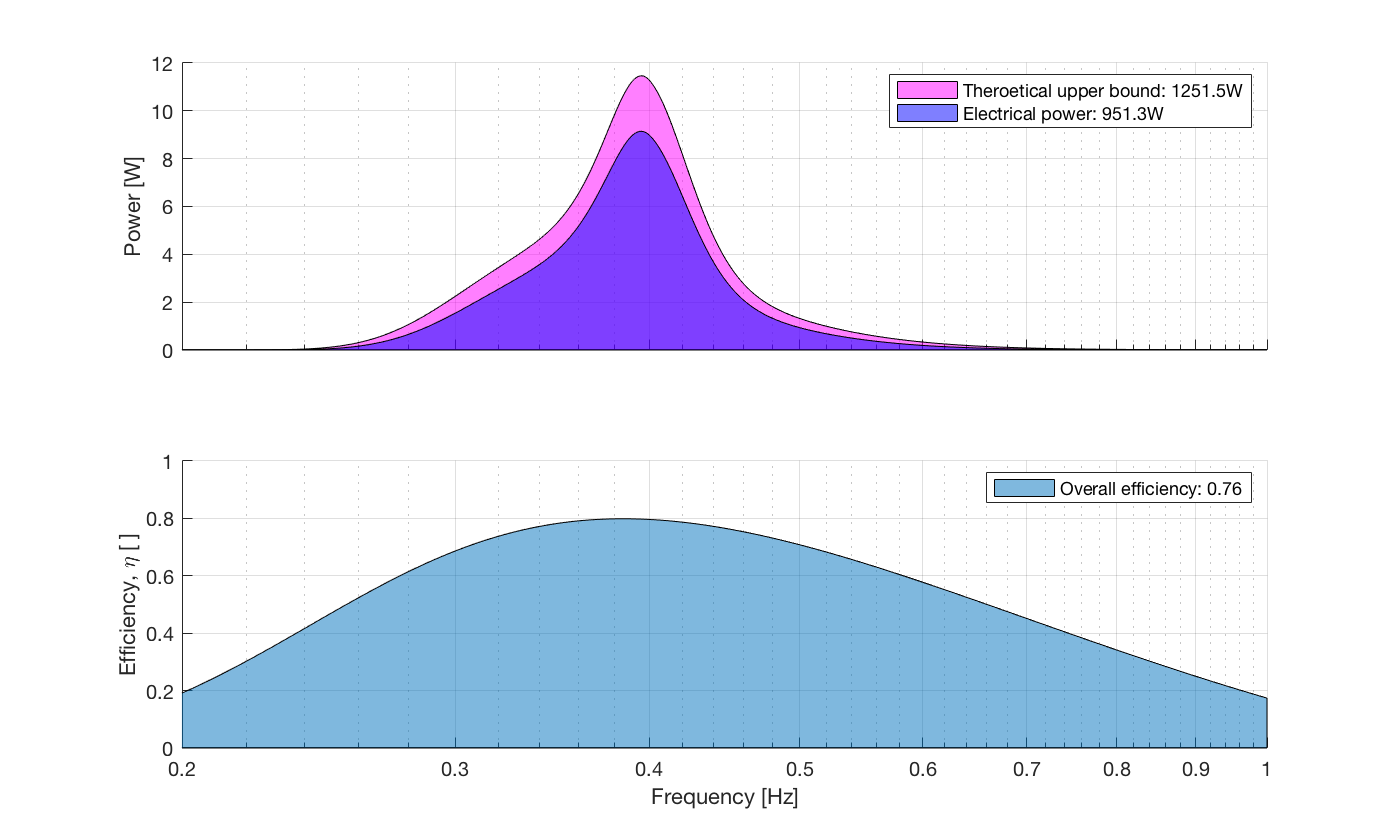

fig2 = figure;
fig2.Position = fig2.Position .* [1 1 1.25 1];

ax(1) = subplot(2,1,1);
hold on
grid on
set(ax(1),'XScale','log')

area(f, P_ub,'facealpha',0.5,'FaceColor','m')
area(f, P_o,'facealpha',0.5,'FaceColor','b')
xlim([0.2,1])
legend(ax(1),...
    sprintf('Theroetical upper bound: %.1fW',P_ub_tot),...
    sprintf('Electrical power: %.1fW',-1*P_tot))
ylabel(ax(1),'Power [W]')
set(ax(1),'xticklabel',[])

ax(2) = subplot(2,1,2);
hold on
grid on
set(ax(2),'XScale','log')
area(f, eta_o, 'facealpha',0.5)
ylim([0 ,1])
xlim([0.2,1])
grid on
ylabel(ax(2),'Efficiency, \eta [ ]')
legend(ax(2),sprintf('Overall efficiency: %.2f',overall_eff))

linkaxes(ax,'x')
xlabel(ax(2),'Frequency [Hz]')

Sandia National Laboratories is a multi-mission laboratory managed and operated by National Technology and Engineering Solutions of Sandia, LLC., a wholly owned subsidiary of Honeywell International, Inc., for the U.S. Department of Energy's National Nuclear Security Administration under contract DE-NA0003525. This document describes objective technical results and analysis. Any subjective views or opinions that might be expressed in the paper do not necessarily represent the views of the U.S. Department of Energy or the United States Government.

% Copyright 2020 National Technology & Engineering Solutions of Sandia, 
% LLC (NTESS). Under the terms of Contract DE-NA0003525 with NTESS, the 
% U.S. Government retains certain rights in this software.
%
% This file is part of fbWecCntrl.
% 
%     fbWecCntrl is free software: you can redistribute it and/or modify
%     it under the terms of the GNU General Public License as published by
%     the Free Software Foundation, either version 3 of the License, or
%     (at your option) any later version.
% 
%     fbWecCntrl is distributed in the hope that it will be useful,
%     but WITHOUT ANY WARRANTY; without even the implied warranty of
%     MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
%     GNU General Public License for more details.
% 
%     You should have received a copy of the GNU General Public License
%     along with fbWecCntrl.  If not, see <https://www.gnu.org/licenses/>.
%
% -------------------------------------------------------------------------